# Top- and Bottom Hat transformation

In this script we try and use the top- and bottom hat transformation to improve the image for detection of holes and other features

When using these results to detect the circles in the image in the **TopBotHatTest.mlx** script and comparing them to the original way we detected the circles, we conclude that this wasn't really usefull.

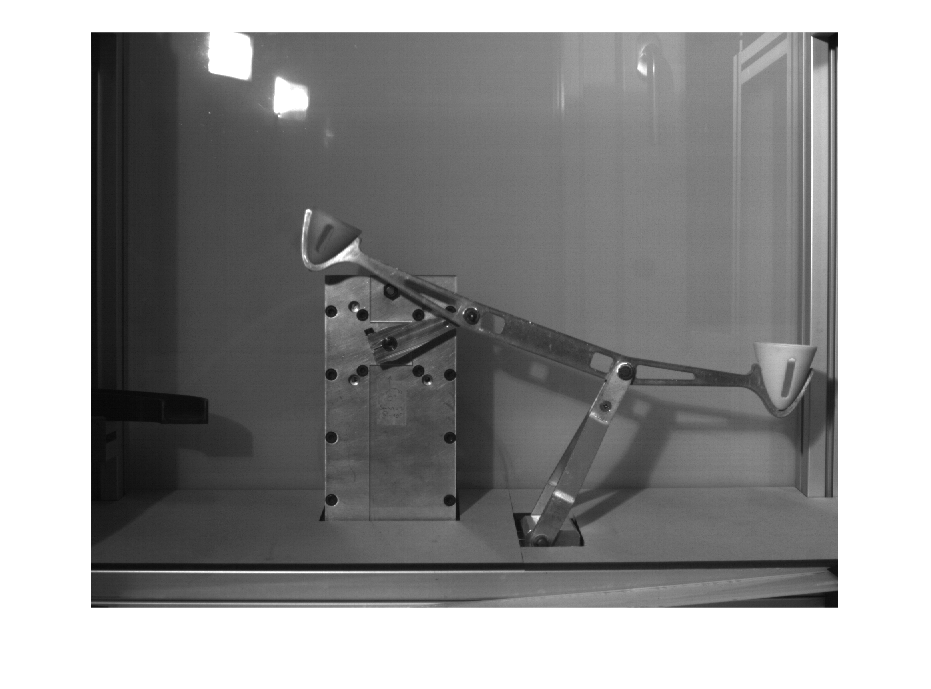

clear
%chunk0 = load('Ballenwerper_sync_380fps_006.npychunk_0.mat');
%chunk1 = load('Ballenwerper_sync_380fps_006.npychunk_0 (1).mat');
chunk2 = load('Ballenwerper_sync_380fps_006.npychunk_2.mat');
chunk3 = load('Ballenwerper_sync_380fps_006.npychunk_3.mat');
chunk4 = load('Ballenwerper_sync_380fps_006.npychunk_4.mat');
chunk5 = load('Ballenwerper_sync_380fps_006.npychunk_5.mat');
chunk6 = load('Ballenwerper_sync_380fps_006.npychunk_6.mat');
chunk7 = load('Ballenwerper_sync_380fps_006.npychunk_7.mat');
chunk8 = load('Ballenwerper_sync_380fps_006.npychunk_8.mat');
chunk9 = load('Ballenwerper_sync_380fps_006.npychunk_9.mat');
 
%videoD1 = cat(1, chunk0.video_data, chunk1.video_data, chunk2.video_data, chunk3.video_data , chunk4.video_data);
videoD2 = cat(1,chunk6.video_data, chunk7.video_data, chunk8.video_data);
videoD3 = cat(1,chunk7.video_data);

%select video
video = videoD3 ; %%ifstatement do

% Total number of frames
numFrames = length(video(:,1,1)); 

frame = video(1,:,:);
frame = squeeze(frame);

%maybe use grayscale dilation!
framead =imadjust(frame,[0 1],[0 1], 0.18);

figure, imshow(frame)

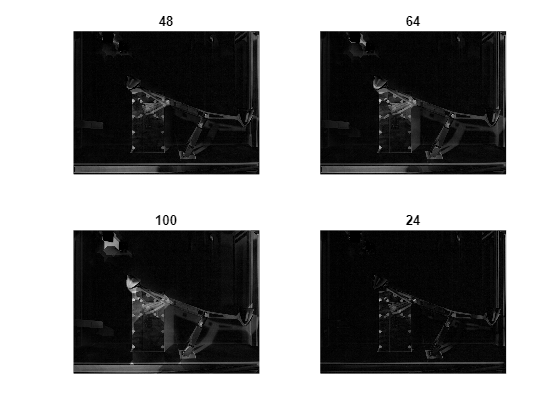



figure
subplot(2,2,1)

se = strel('disk',48);
tophatFiltered = imbothat(frame,se);
imshow(tophatFiltered)
title("48")

subplot(2,2,2)

se = strel('disk',64);
tophatFiltered = imbothat(frame,se);
imshow(tophatFiltered)
title("64")

subplot(2,2,3)

se = strel('disk',100);
tophatFiltered = imbothat(frame,se);
imshow(tophatFiltered)
title("100")

subplot(2,2,4)

se = strel('disk',24);
tophatFiltered = imbothat(frame,se);
imshow(tophatFiltered)
title("24")

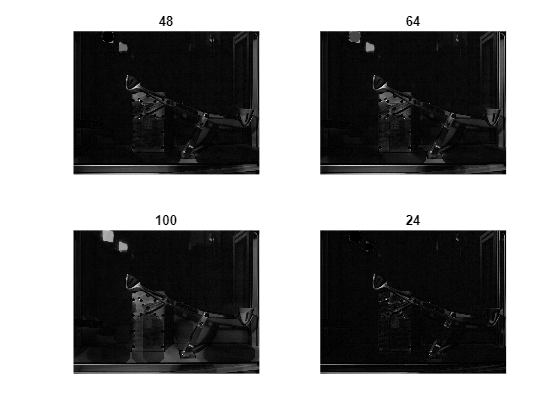



figure
subplot(2,2,1)

se = strel('disk',48);
tophatFiltered = imtophat(frame,se);
imshow(tophatFiltered)
title("48")

subplot(2,2,2)

se = strel('disk',64);
tophatFiltered = imtophat(frame,se);
imshow(tophatFiltered)
title("64")

subplot(2,2,3)

se = strel('disk',100);
tophatFiltered = imtophat(frame,se);
imshow(tophatFiltered)
title("100")

subplot(2,2,4)

se = strel('disk',24);
tophatFiltered = imtophat(frame,se);
imshow(tophatFiltered)
title("24")